close all; clc

% find equilibrium points
syms a positive
syms b nonzero
syms x1 x2

% find equilibrium points
f1 = x2;
f2 = x1 - 2*atan(x1+x2);

sln = solve([f1==0, f2==0], [x1 x2]);

sln.x1

$$ans = 0$$

sln.x2

$$ans = 0$$

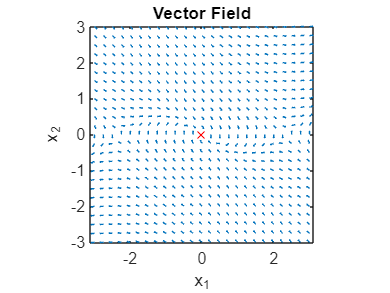

% Create vector field
x = linspace(-3,3,25);
y = linspace(-3,3,25);
[X,Y] = meshgrid(x,y);

DX = Y;
DY = X - 2*atan(X+Y);

N = sqrt(DX.^2 + DY.^2);
quiver(X,Y,DX./N,DY./N,0.3);
xlabel('x_1')
ylabel('x_2')
axis tight equal;
title("Vector Field")

% draws x's on the real equilibrium points
hold on;
for i=1:numel(sln.x1)
    if isreal(sln.x1(i)) && isreal(sln.x2(i))
        plot(sln.x1(i), sln.x2(i), 'rx')
    end
end
hold off